# Solución ejercicio 1

Ocuparemos la posición y orientación conocida de los objetos para su captura

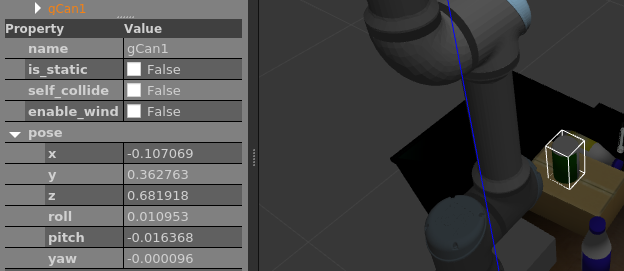

Se propone la siguiente secuencia de operacion

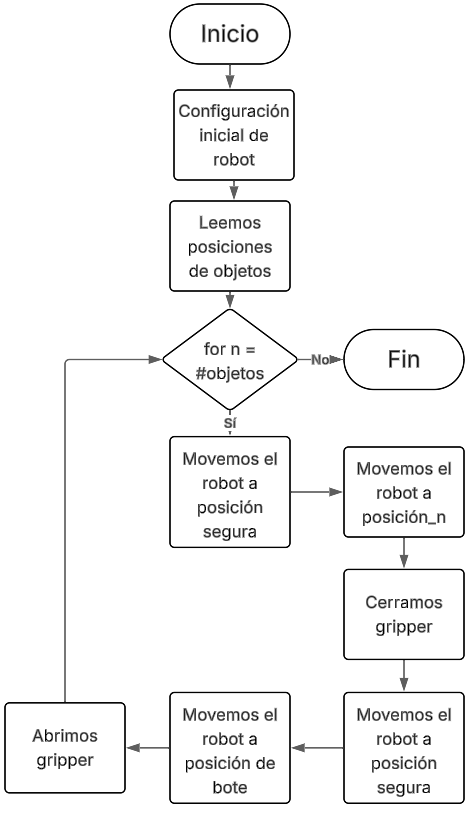

## Ejercicio resuelto

clear all
% Configuración inicial del robot
rosIP = '172.17.0.1';
[jointSub,trajGoal,trajAct,gripGoal,gripAct,rgbImgSub,rgbDptSub] = IniciarRobot(rosIP);

Initializing global node /matlab_global_node_19755 with NodeURI http://PCIrandi:38645/ and MasterURI http://172.17.0.1:11311.
/camera/depth/camera_info                                  
/camera/depth/image_raw                                    
/camera/depth/points                                       
/camera/parameter_descriptions                             
/camera/parameter_updates                                  
/camera/rgb/camera_info                                    
/camera/rgb/image_raw                                      
/clock                                                     
/ft_sensor/raw                                             
/gazebo/link_states                                        
/gazebo/model_states                                       
/gazebo/parameter_descriptions                             
/gazebo/parameter_updates                                  
/gazebo/performance_metrics                                
/gazebo/set_link_state            


q = zeros(6,1);

%% Buscamos la posición de algunos objetos y botes de disposición final de forma manual
gripperX = -0.38;
gripperY = -0.4;
gripperZ = 0.2;

gripperTheta = 3.14;


q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);

%Leemos posiciones objetos
objeto(1) = struct('objeto', 0 , 'x', -0.0068, 'y', 0.3628 , 'z' ,  0.0670 , 'orientacion', 0 , 'Bote', 0);
objeto(2) = struct('objeto', 1 , 'x', -0.0430, 'y', 0.5262 , 'z' , -0.090 , 'orientacion', 1.57 , 'Bote', 1);
objeto(3) = struct('objeto', 2 , 'x',  0.3768, 'y', 0.4638 , 'z' , -0.0500 , 'orientacion', 1.57 , 'Bote', 1);

bote(1) = struct('color', 0 , 'x', -0.38, 'y', 0.4 , 'z' ,  0.2 , 'orientacion', 0  );
bote(2) = struct('color', 1 , 'x', -0.38, 'y', -0.4 , 'z' ,  0.2 , 'orientacion', 3.14  );


%Ciclo for recorriendo todos los objetos
for n = 1:numel(objeto)
    %Movemos el gripper a posición segura
    gripperX = objeto(n).x;
    gripperY = objeto(n).y;
    gripperZ = objeto(n).z;
    gripperTheta = objeto(n).orientacion;

    q = MoverRobotXYZ(gripperX,gripperY,0.3,gripperTheta,q,trajAct,trajGoal,jointSub);
    
    %Movemos el gripper a posición de captura 
    q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);
    
    %Movemos el gripper a posición segura
    q = MoverRobotXYZ(gripperX,gripperY,0.3,gripperTheta,q,trajAct,trajGoal,jointSub);
end

%Ciclo for recorriendo todos los objetos
for n = 1:numel(objeto)
    %Movemos el gripper a posición segura
    gripperX = objeto(n).x;
    gripperY = objeto(n).y;
    gripperZ = objeto(n).z;
    gripperTheta = objeto(n).orientacion;

    q = MoverRobotXYZ(gripperX,gripperY,0.3,gripperTheta,q,trajAct,trajGoal,jointSub);
    
    %Movemos el gripper a posición de captura 
    q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);
    
    %Movemos el gripper a posición segura
    q = MoverRobotXYZ(gripperX,gripperY,0.3,gripperTheta,q,trajAct,trajGoal,jointSub);

    %Movemos el gripper a posición bote
    if objeto(n).Bote == bote(1).color
        gripperX = bote(1).x;
        gripperY = bote(1).y;
        gripperZ = bote(1).z;
        gripperTheta = objeto(1).orientacion;
    else
        gripperX = bote(2).x;
        gripperY = bote(2).y;
        gripperZ = bote(2).z;
        gripperTheta = objeto(2).orientacion;
    end
    q = MoverRobotXYZ(gripperX,gripperY,0.3,gripperTheta,q,trajAct,trajGoal,jointSub);

end

## Abriendo y cerrando el gripper

En simulación, cada pieza requiere un ajuste de las pinzas.

%Movimiento a zona de recolección
n = 3;
gripperX = objeto(n).x;
gripperY = objeto(n).y;
gripperZ = objeto(n).z;
gripperTheta = objeto(n).orientacion;
q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);


% Movimeinto a zona de seguridad
n = 1;
gripperX = objeto(n).x;
gripperY = objeto(n).y;
gripperZ = objeto(n).z;
gripperTheta = objeto(n).orientacion;
q = MoverRobotXYZ(gripperX,gripperY,0.3,gripperTheta,q,trajAct,trajGoal,jointSub);


ValorGripper = 0;    %0 abierto/desactivado 0.8 cerrado/activado
ActivacionGripper(ValorGripper,gripAct,gripGoal,jointSub);
%Función que abre y cierra el gripper, para que esta función se itere hasta
%que culmine la acciòn deberá entrar al código y descomentar la sección
%correspondiente

objeto(1).gripper = 0.25;
objeto(2).gripper = 0.21;
objeto(3).gripper = 0.33;

Solucion final

clear all
% Configuración inicial del robot
rosIP = '172.17.0.1';
[jointSub,trajGoal,trajAct,gripGoal,gripAct,rgbImgSub,rgbDptSub] = IniciarRobot(rosIP);

Shutting down global node /matlab_global_node_63575 with NodeURI http://PCIrandi:34777/ and MasterURI http://172.17.0.1:11311.
Initializing global node /matlab_global_node_16179 with NodeURI http://PCIrandi:37085/ and MasterURI http://172.17.0.1:11311.
/camera/depth/camera_info                                  
/camera/depth/image_raw                                    
/camera/depth/points                                       
/camera/parameter_descriptions                             
/camera/parameter_updates                                  
/camera/rgb/camera_info                                    
/camera/rgb/image_raw                                      
/clock                                                     
/ft_sensor/raw                                             
/gazebo/link_states                                        
/gazebo/model_states                                       
/gazebo/parameter_descriptions                             
/gazebo/parameter_updates  

q = zeros(6,1);
tiempo_pausa = 2;

% Leemos posiciones de objetos
objeto(1) = struct('objeto', 0 , 'x', -0.0068, 'y', 0.3628 , 'z' ,  0.080 , 'orientacion', 0.00 , 'Bote', 0 , 'gripper' , 0.23);
objeto(2) = struct('objeto', 1 , 'x', -0.0450, 'y', 0.5000 , 'z' , -0.0900 , 'orientacion', 1.57 , 'Bote', 1 , 'gripper' , 0.21);
objeto(3) = struct('objeto', 2 , 'x',  0.3768, 'y', 0.4638 , 'z' , -0.0500 , 'orientacion', 1.57 , 'Bote', 1 , 'gripper' , 0.30);

bote(1) = struct('color', 0 , 'x', -0.38, 'y', 0.4 , 'z' ,  0.2 , 'orientacion', 0  );
bote(2) = struct('color', 1 , 'x', -0.38, 'y', -0.4 , 'z' ,  0.2 , 'orientacion', 3.14  );

%Ciclo for recorriendo todos los objetos
for n = 1:numel(objeto)
    %Movemos el gripper a posición segura
    gripperX = objeto(n).x;
    gripperY = objeto(n).y;
    gripperZ = objeto(n).z;
    gripperTheta = objeto(n).orientacion;

    q = MoverRobotXYZ(gripperX,gripperY,0.3,gripperTheta,q,trajAct,trajGoal,jointSub);
    pause(tiempo_pausa);
    
    %Movemos el gripper a posición de captura 
    q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);
    pause(tiempo_pausa);
    
    %Cerramos gripper
    ValorGripper = objeto(n).gripper;    %0 abierto/desactivado 0.8 cerrado/activado
    ActivacionGripper(ValorGripper,gripAct,gripGoal,jointSub);
    pause(tiempo_pausa);

    %Movemos el gripper a posición segura
    q = MoverRobotXYZ(gripperX,gripperY,0.3,gripperTheta,q,trajAct,trajGoal,jointSub);
    pause(tiempo_pausa);

    %Movemos el gripper a posición bote
    if objeto(n).Bote == bote(1).color
        gripperX = bote(1).x;
        gripperY = bote(1).y;
        gripperZ = bote(1).z;
        gripperTheta = objeto(1).orientacion;
    else
        gripperX = bote(2).x;
        gripperY = bote(2).y;
        gripperZ = bote(2).z;
        gripperTheta = objeto(2).orientacion;
    end
    q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);
    pause(tiempo_pausa);

    %Cerramos gripper
    ValorGripper = 0;    %0 abierto/desactivado 0.8 cerrado/activado
    ActivacionGripper(ValorGripper,gripAct,gripGoal,jointSub);
    pause(tiempo_pausa);

    ValorGripper = 1;    %0 abierto/desactivado 0.8 cerrado/activado
    ActivacionGripper(ValorGripper,gripAct,gripGoal,jointSub);
    pause(tiempo_pausa);

    ValorGripper = 0;    %0 abierto/desactivado 0.8 cerrado/activado
    ActivacionGripper(ValorGripper,gripAct,gripGoal,jointSub);
    pause(tiempo_pausa);

end